Import data

data = readmatrix('data.csv');
x = data(:,3:32);
y = data(:,2);
m = length(y);

Visualization of the data

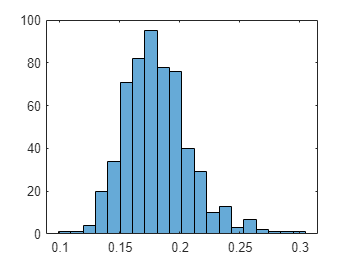

histogram(x(:,9),20);

%plot(x(:,3),y,'o');

Normalize the data betweem 0 -> 1

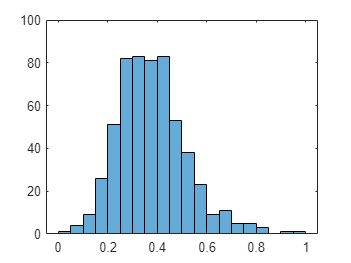

y2 = log(1+y);
for i=3:30
    x2(:,i) = (x(:,i)-min(x(:,i)))/(max(x(:,i))-min(x(:,i)));
end
histogram(x2(:,9),20);

Train the ANN 